% The Nelder-Mead Simplex Method  - From HW5 Question 1


Change the **objective function at the bottom of the code**

**Change the contour function at line 20. **

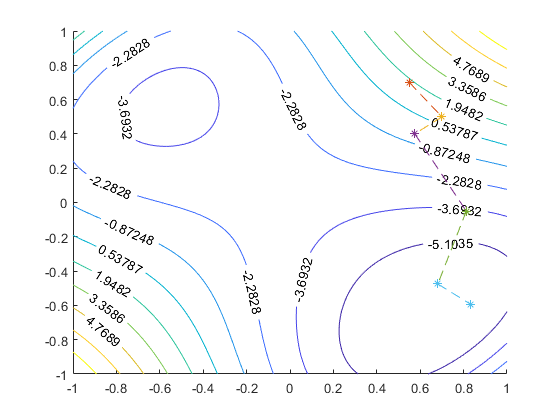

&&&&&&&&&&&&&& iteration # 0 &&&&&&&&&&&&&&&&&&&

Point of Centroid at iterattion # 0

Pg =     0.6000
    0.7000


Point of Reflection at iteration # 0

Pr =     0.6500
    0.6000


Point of Expansion at iteration # 0

Pe =     0.7000
    0.5000


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

&&&&&&&&&&&&&& iteration # 1 &&&&&&&&&&&&&&&&&&&

Point of Centroid at iterattion # 1

Pg =     0.6250
    0.6000


Point of Reflection at iteration # 1

Pr =     0.6000
    0.5000


Point of Expansion at iteration # 1

Pe =     0.5750
    0.4000


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

&&&&&&&&&&&&&& iteration # 2 &&&&&&&&&&&&&&&&&&&

Point of Centroid at iterattion # 2

Pg =     0.6375
    0.4500


Point of Reflection at iteration # 2

Pr =     0.7250
    0.2000


Point of Expansion at iteration # 2

Pe =     0.8125
   -0.0500


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

&&&&&&&&&&&&&& iteration # 3 &&&&&&&&&&&&&&&&&&&

Point of Centroid at iterattion # 3

Pg =     0.6938
    0.1750


Point of Reflection at iteration # 3

Pr =     0.6875
   -0.1500


Point of Expansion at iteration # 3

Pe =     0.6813
   -0.4750


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

&&&&&&&&&&&&&& iteration # 4 &&&&&&&&&&&&&&&&&&&

Point of Centroid at iterattion # 4

Pg =     0.7469
   -0.2625


Point of Reflection at iteration # 4

Pr =     0.9188
   -0.9250


Point of Outside Contraction at iteration # 4

Pc =     0.8328
   -0.5937


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%Starting Point
x0=[0.55;0.7];
N=3;  %%%%%%%%%PLEASE DECIDE THE NO. OF POINTS ACCORDING TO DIMENSIONS OF STARTING POINT %%%%%%%%%%%%%

% Inputs
lamda=0.1; e1=[1 0]'; e2=[0 1]'; ro=1; chi=2; gamma=1/2; sigma=1/2;

% So for a two dimensional function we must have n+1 points so following
% are three points
x(:,3)=x0;
x(:,1)=x0+lamda*e1;
x(:,2)=x0+lamda*e2;

%Plot
hold on
[X1,X2]=meshgrid(-1:0.01:1);
Y=(X2-X1).^4+12.*X1.*X2-X1+X2-3; %% <-- CHANGE CONTOUR FUNCTION %%%%%%%%
[V,h] = contour(X1,X2,Y,10);
clabel(V,h);
plot(x0(1),x0(2),'--*')
iteration =0;
while iteration < 5 %%<----------Change the 5 to desired value.
    fprintf('&&&&&&&&&&&&&& iteration # %g &&&&&&&&&&&&&&&&&&&', iteration)

    z=x(:,3);
    % Sorting the matrix to arrange in the ascending order of objective
    % function values
    for i=1:(N-1)
        for j=1:(N-i)
            if(fun(x(:,j))> fun(x(:,j+1)))
            a=x(:,j);
            x(:,j)=x(:,j+1);
            x(:,j+1)=a;
            end
        end
    end
    x=x;
    
    % Stopping Criteria
    size=norm(x(:,1)-x(:,2))+norm(x(:,2)-x(:,3))+norm(x(:,3)-x(:,1));
    if (size<1e-6)
        break;
    end
    % Finding Centroid Point
    fprintf('Point of Centroid at iterattion # %g', iteration)
    Pg=1/2*((x(:,1)+x(:,2))) %note x(:,1) is smallest point , x(:,2) is next largest point
    
    % Checking Different Points
    % 1) Reflection Point
    fprintf('Point of Reflection at iteration # %g', iteration)
    Pr=Pg+ro*(Pg-x(:,3))
    if (fun(Pr)>=fun(x(:,1)) && fun(Pr)<fun(x(:,2)))
        x(:,3)=Pr;
    elseif (fun(Pr)<fun(x(:,1)))
        % 2) Expansion Move
            fprintf('Point of Expansion at iteration # %g', iteration)
        Pe=Pg+chi*(Pr-Pg)
        if (fun(Pe)<fun(Pr))
            x(:,3)=Pe;
        else
            x(:,3)=Pr;
        end
    elseif (fun(Pr)>fun(x(:,2)) && fun(Pr)<fun(x(:,3)))
        % 3) Outside Contraction Move
        fprintf('Point of Outside Contraction at iteration # %g', iteration)

        Pc=Pg+gamma*(Pr-Pg)
        if (fun(Pc)<fun(x(:,3)))
            x(:,3)=Pc;
        end
    else (fun(Pr)>fun(x(:,3)))
        % 4) Inside Contraction Move
        fprintf('Point of Inside Contraction at iteration # %g', iteration)
        Pcc=Pg+gamma*(x(:,3)-Pg)
        if fun(Pcc)<fun(x(:,3))
            x(:,3)=Pcc;
        else
            x(:,2)=1/2*(x(:,1)+x(:,2));
            x(:,3)=1/2*(x(:,1)+x(:,3));
        end
    end
    fprintf('%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%')
     plot([z(1),x(1,3)],[z(2),x(2,3)],'--*');
     iteration= iteration +1;
end

x(:,1)

ans =     0.6813
   -0.4750


function y = fun(x)
    y=(x(1)-x(2))^4+12*x(1)*x(2)-x(1)+x(2)-3;
end
